clearvars; close('all');
% GNSS headng
compass = 'GNSS';

% load("data\CS_GNSS.mat");region='Celtic Sea';
% load("data\RT_GNSS.mat"); region='Rockall Trough';

% sig compasss
compass = 'signature';
load("data\CS_SIG.mat"); region='Celtic Sea';
load("data\RT_SIG.mat");region='Rockall Trough';


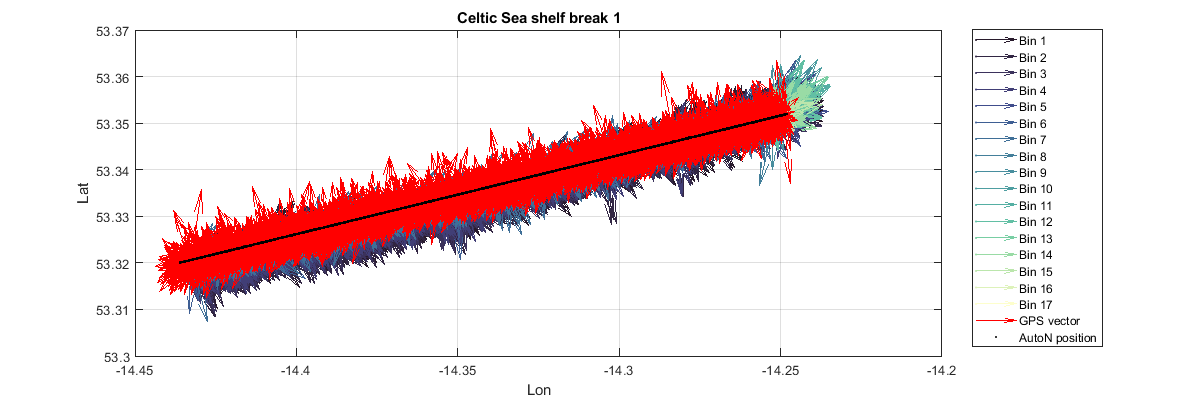

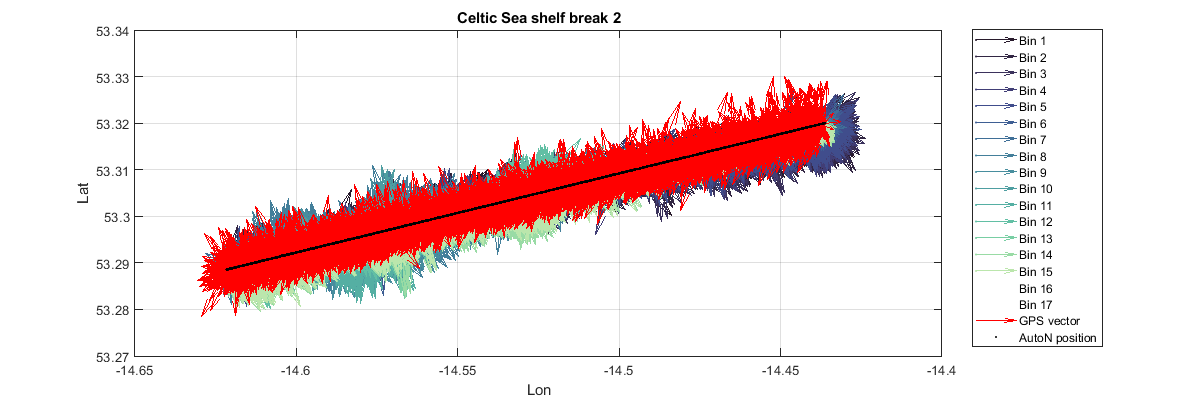

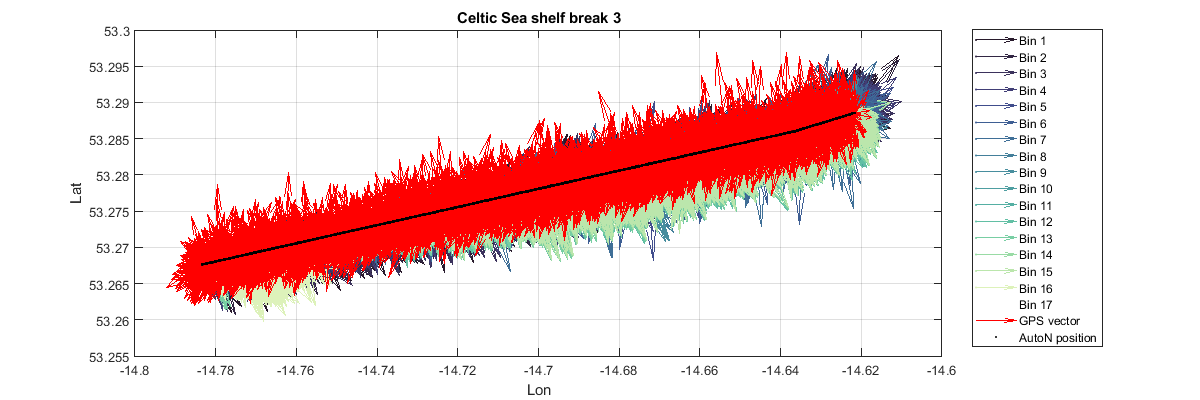

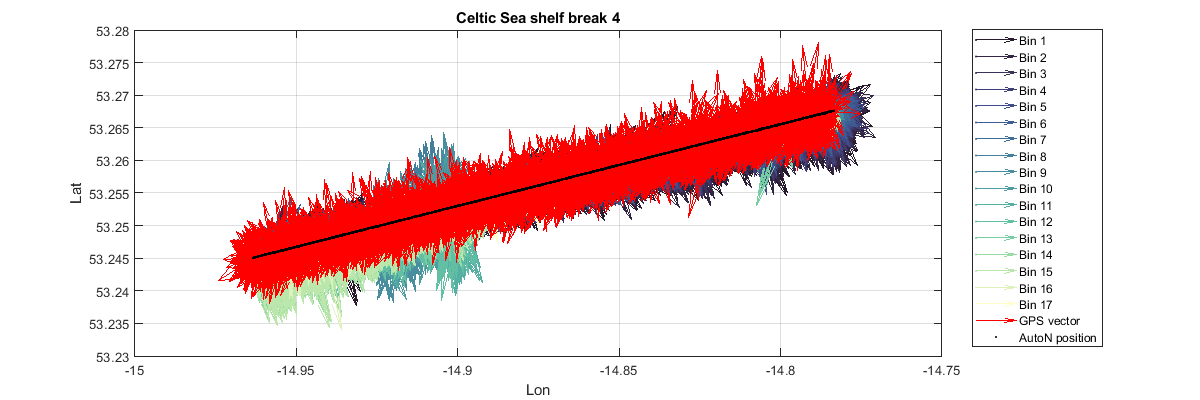

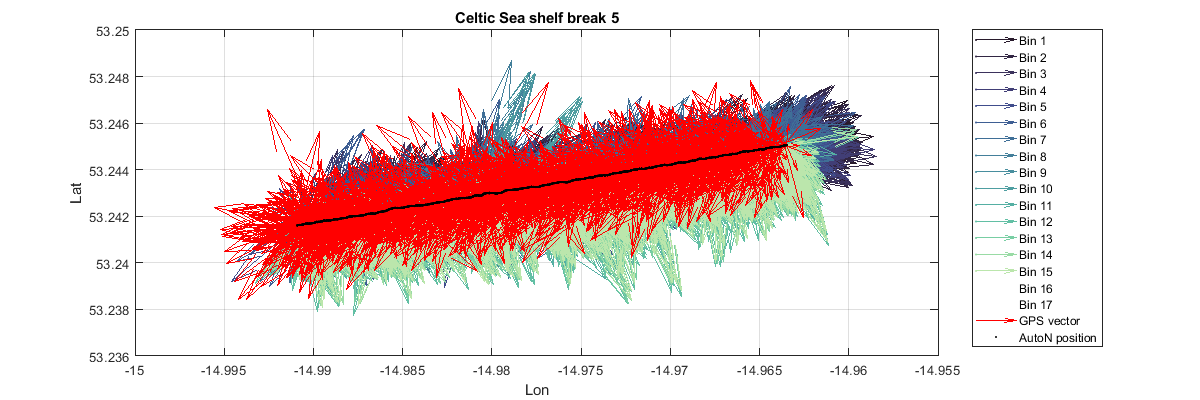

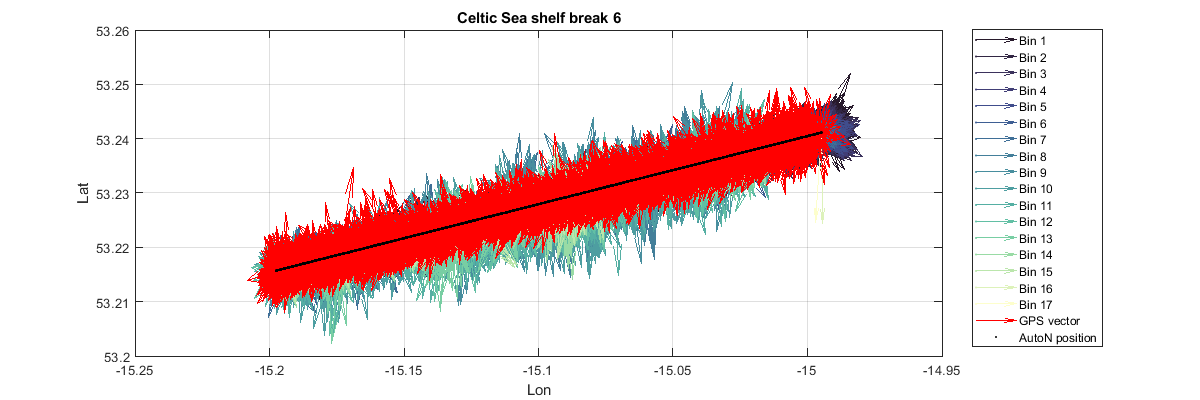

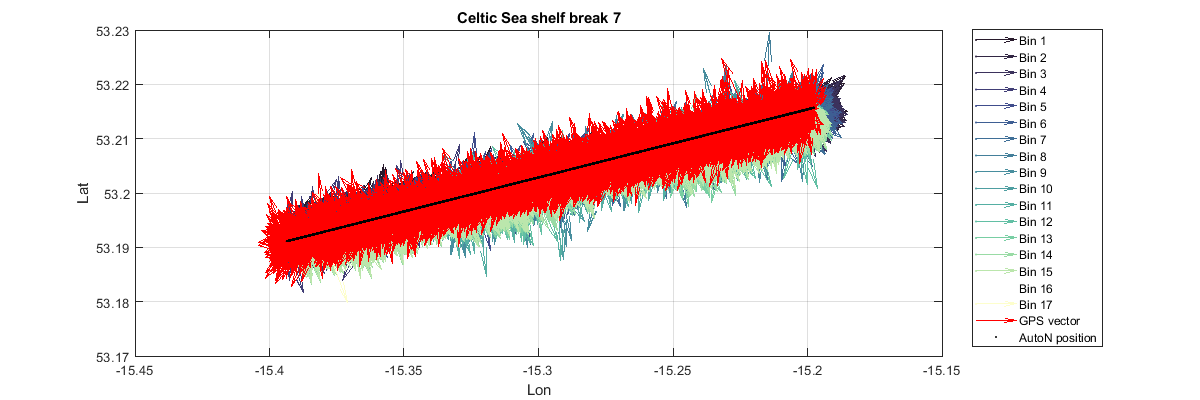

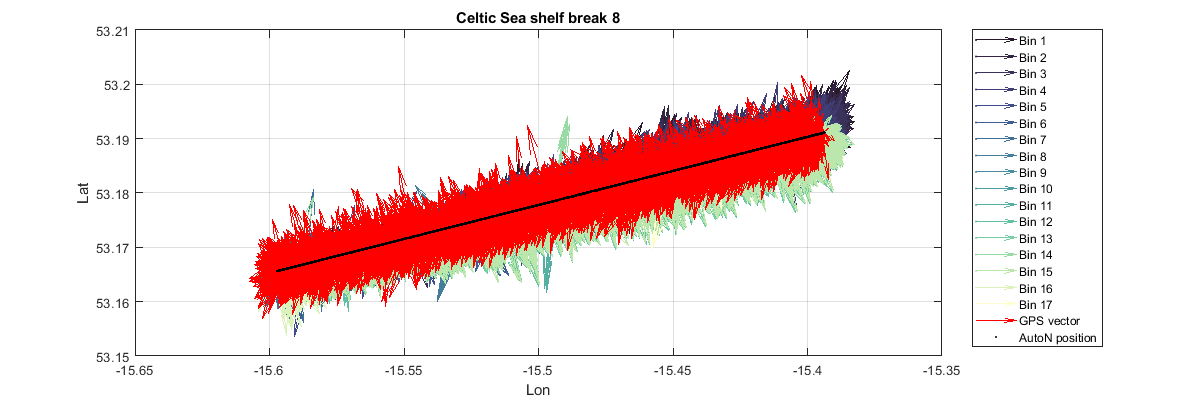

clrs=cmocean('-Deep',17);

for mm = 1:numel(WatStruct)

   figure('Renderer', 'painters', 'Position', [10 20 1200 400])
    
   for ii = 1:17
        X=NavStruct(mm).long_deg; x=X';
        x=repmat(x,17,1);
        Y=NavStruct(mm).lat_deg;y=Y';
        y=repmat(y,17,1);
        u=WatStruct(mm).vEast_ms;
        v=WatStruct(mm).vNorth_ms;
%         Q=quivers(x,y,u,v,2,1,'m/s',[clrs(ii,:) 0.5]);

        Q=quiver(x(ii,:),y(ii,:),u(ii,:),v(ii,:),...
            'AutoScaleFactor',12,...
            'LineWidth',0.2,...
            'MaxHeadSize',0.5,...
            "Color",[clrs(ii,:) 0.5],...
            'Marker','.',...
            'MarkerFaceColor','k');
        legstr{ii}=['Bin ' num2str(ii)];
        hold on
   end
   ug=NavStruct(mm).gpsVeast; vg=NavStruct(mm).gpsVnorth;
   q=quiver(X,Y,ug,vg,'AutoScaleFactor',12,'LineStyle','-','LineWidth',0.02,'Color','r');
%    ,...
%         'AutoScaleFactor',12,...
%         'LineStyle',:,...
%         'LineWidth',0.02,...
%         'MaxHeadSize',0.5,...
%         "Color",'r');
    
    p1=plot(X,Y,'k.');
    legstr{ii+1}='GPS vector';
    legstr{ii+2}='AutoN position';
    grid on
    xlabel('Lon');
    ylabel('Lat');
    title([region ' shelf break ' num2str(mm)]) ;
    legend(legstr,'Location',"bestoutside");
%     print(gcf,'-dpng',['figures/' region '_vec_GNSS_' num2str(mm)]) ;  
    print(gcf,'-dpng',['figures/' region '_vec_' compass '_' num2str(mm)]) ;  
end